# Import Data Demo

This Live script explain how to add interactively new exergy or resource data to the model.

### Read Data Model

data=ReadDataModel('cgam_model.json');

### Import Exergy Data

The file `ExergyData.csv `contain the exergy values of a simulaton of the CGAM plant (decreasing APH efficiency)

The file is imported into a `cTable` that contains the exergy values in the first column

tbl=ImportData('ExergyData.csv','Description','Exergy Data Test');
val=tbl.getColumnValues(1);

#### Add the new exergy data to the data model

These values are loaded into a new state called` 'Test', `with the function `addExergyData.`

Data model must be updated, using function `updateModel`, if we can show and use the new state:

data.addExergyData('Test',val);
disp(data.StateNames);

    {'REF'}    {'T1180'}    {'ETG87'}    {'ECMP84'}    {'RP8'}    {'PINCH15'}    {'CGAMR'}    {'noAPH'}    {'Test'}



data.updateModel;
ShowResults(data,'Table','Exergy');


Exergy Data

 key          REF       T1180       ETG87      ECMP84         RP8     PINCH15       CGAMR       noAPH        Test 
————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
 NG        72.465      73.327        73.6      73.297      72.283      72.465      72.465     109.913      82.457 
 B1             0           0           0           0           0           0           0           0           0 
 B2        28.651      29.507      29.337      29.196      27.863      28.651      28.651      28.228      30.735 
 B3        50.339      50.896      51.926      51.018      51.048      50.339      50.339      28.228      51.015 
 B4        102.53     103.462     104.971     103.813     103.163      102.53      102.53     101.759     110.079 
 B5         38.81      38.735       40.23      39.295      40.324       38.81       38.81      38.518      43.232 
 B6        14.784      15.021      15.213      15.137      14.59

res=ThermoeconomicAnalysis(data,'State','Test');
ShowResults(res,'Table','dfcost');


Flows Exergy Cost - Test

Key         B(MW)      B*(MW)    Bin*(MW)     Br*(MW)      k*(J/J)    kin*(J/J)     kr*(J/J)
—————————————————————————————————————————————————————————————————————————————————————————————
NG         82.457      82.457      82.457       0.000       1.0000       1.0000       0.0000
B1          0.000       0.000       0.000       0.000       0.0000       0.0000       0.0000
B2         30.735      58.759      56.495       2.264       1.9118       1.8381       0.0737
B3         51.015      98.021      94.218       3.803       1.9214       1.8469       0.0746
B4        110.079     182.685     176.675       6.010       1.6596       1.6050       0.0546
B5         43.232      71.747      69.387       2.360       1.6596       1.6050       0.0546
B6         19.728      32.740      31.663       1.077       1.6596       1.6050       0.0546
B7          1.731       2.873       2.778       0.094       1.6596       1.6050       0.0546
WC         33.367      58.492      56.495 

### Import Resource Cost data

Import the files `ResouceFlows.csv` that contains the unit cost of resource flows and `ResourceProcesses.csv `that contains the cost of processes.

tbl=ImportData('ResourceFlows.csv');
rval=tbl.getColumnData(2);
tbl=ImportData('ResourceProcesses.csv');
pval=tbl.getColumnValues(2);

Create a new resource sample `'Test' `with this data values.

data.addResourceData('Test',rval,pval);
disp(data.SampleNames);

    {'Base'}    {'CGAMR'}    {'Test'}



#### Update the model and show results

data.updateModel;
ShowResults(data,'Table','ResourcesCost');


Resources Cost

 key    type            Base       CGAMR        Test 
———————————————————————————————————————————————————————
 NG     FLOW              30          30          35 
 B1     FLOW               0           0        0.01 
 COMB   PROCESS          3.6         3.6         3.7 
 CMP    PROCESS         32.5        32.5          34 
 TRB    PROCESS           46          46          48 
 APH    PROCESS           20          20          21 
 HRSG   PROCESS           35           0          37 
 STCK   PROCESS            0           0           0 



### Make thermoeconomic analysis with the modified data model

model=ThermoeconomicModel(data,'State','Test','CostTables','ALL','Summary','STATES','Recycling',true);

INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [REF] are valid
INFO: cDataModel. Exergy values [T1180] are valid
INFO: cDataModel. Exergy values [ETG87] are valid
INFO: cDataModel. Exergy values [ECMP84] are valid
INFO: cDataModel. Exergy values [RP8] are valid
INFO: cDataModel. Exergy values [PINCH15] are valid
INFO: cExergyData. Process HRSG is not active
INFO: cDataModel. Exergy values [CGAMR] are valid
INFO: cExergyData. Process APH is not active
INFO: cDataModel. Exergy values [noAPH] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. Resources Cost sample [Base] is valid
INFO: cDataModel. Resources Cost sample [CGAMR] is valid
INFO: cDataModel. Data model cgam_model is valid
INFO: cThermoeconomicModel. Productive Diagram Active
INFO: cThermoeconomicModel. Set state Test
INFO: cThermoeconomicModel. Compute Diagram FP
INFO: cThermoeconomicModel. Compute thermoeconomic analysis for sta

model.setDebug(false);

#### **Select and show the result tables**

tables=string(model.ListOfTables);
ShowResults(model,'Table',char(tables(7)));


FP Table (MW) - Test

 Key            COMB        CMP        TRB        APH       HRSG       STCK        ENV      Total
——————————————————————————————————————————————————————————————————————————————————————————————————
 COMB          0.000      0.000     66.847     23.504     17.997      1.731      0.000    110.079
 CMP          30.735      0.000      0.000      0.000      0.000      0.000      0.000     30.735
 TRB           0.000     33.367      0.000      0.000      0.000      0.000     30.000     63.367
 APH          20.280      0.000      0.000      0.000      0.000      0.000      0.000     20.280
 HRSG          0.000      0.000      0.000      0.000      0.000      0.000     12.956     12.956
 STCK          0.000      0.000      0.000      0.000      0.000      0.000      1.731      1.731
 ENV          82.457      0.000      0.000      0.000      0.000      0.000      0.000     82.457
——————————————————————————————————————————————————————————————————————————————————————————————

#### **Select and show the result graphs**

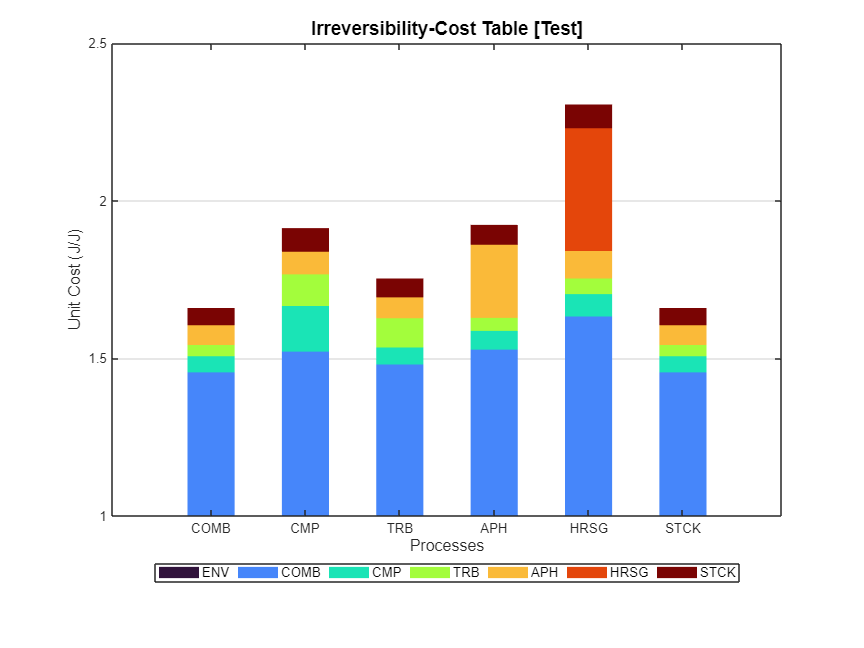

graphs=string(model.ListOfGraphs);
ShowGraph(model,'Graph',char(graphs(3)));

### **Summary Results**

Select and show Summary Tables

res=model.summaryResults;
stables=string(res.ListOfTables);
ShowResults(res,'Table',char(stables(1)));


Flows Exergy (MW) - SUMMARY

 key           REF      T1180      ETG87     ECMP84        RP8    PINCH15      CGAMR      noAPH       Test
———————————————————————————————————————————————————————————————————————————————————————————————————————————
 NG         72.465     73.327     73.600     73.297     72.283     72.465     72.465    109.913     82.457
 B1          0.000      0.000      0.000      0.000      0.000      0.000      0.000      0.000      0.000
 B2         28.651     29.507     29.337     29.196     27.863     28.651     28.651     28.228     30.735
 B3         50.339     50.896     51.926     51.018     51.048     50.339     50.339     28.228     51.015
 B4        102.530    103.462    104.971    103.813    103.163    102.530    102.530    101.759    110.079
 B5         38.810     38.735     40.230     39.295     40.324     38.810     38.810     38.518     43.232
 B6         14.784     15.021     15.213     15.137     14.597     14.784     14.784     38.518     19.728
 B7   

Select and show Summary Graphs

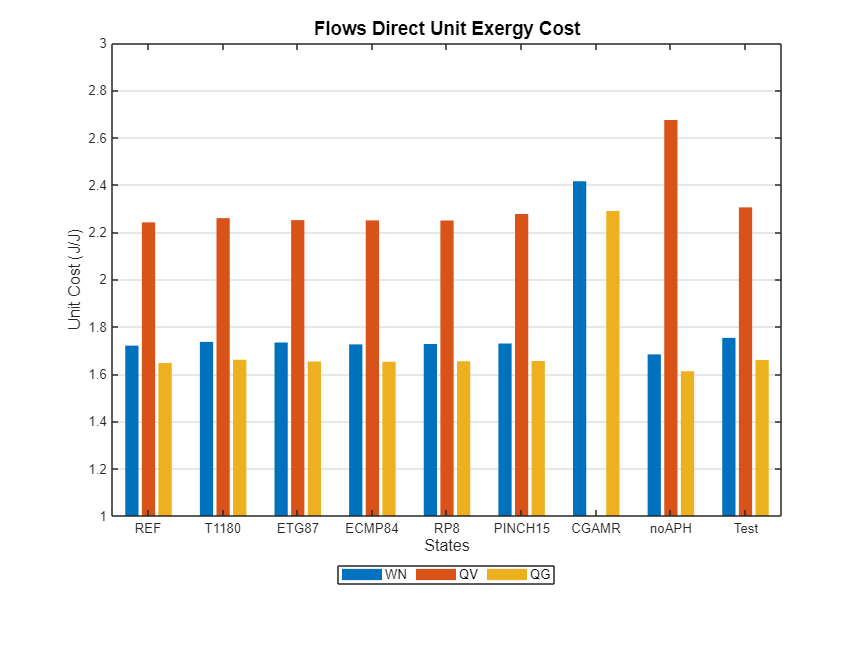

sgraphs=string(res.ListOfGraphs);
ShowGraph(res,'Graph',char(sgraphs(3)));

### Additional Help Information

help ImportData

 ImportData - Import external data to a cTableData from CSV or XLSX files.
 
    Syntax
      res=ImportData(filename,Name,Value)
   
    Input Arguments
      filename - Name of the file, including .xlsx extension
        char array
 
    Name-Value Arguments
      Name: Name of the table. 
        char array       
      Description: Description of the table
        char array
      Sheet: Name of the data sheet, in case of XLSX files.
        If ommitted the first sheet is used.
        char array
      If Name or Description are omitted, when filename is CSV use
        the name of the file without extension, when filename is XLSX
        use the name of the sheet
 
    Output Arguments
      tbl - cTableData with the content of the file/sheet
 
    Example
      Import Data Demo
   
    See also cTableData

    